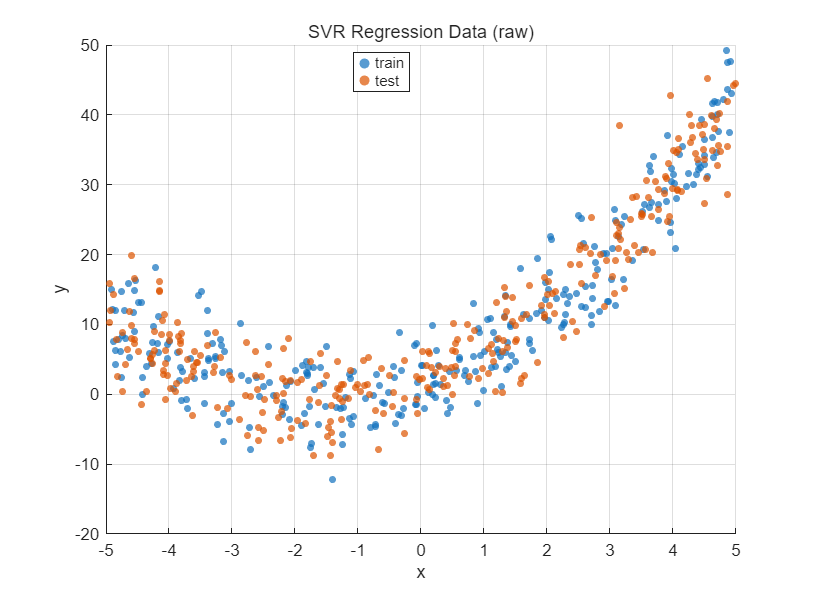

%% SVR Regression Demo (MATLAB version of your sklearn code)
% 对应：生成数据 -> train/test split -> Baseline SVR(RBF)+Standardize
%      -> gamma 批量观察 -> Grid Search + 5-fold CV -> test evaluation
%      -> Pred vs True -> Residual histogram

clear; clc; close all;

tic;  % 对应 Python 的 tic()

%% 1) 生成数据：y = 2 + 3x + x^2 + noise
n = 600;
seed = 42;
noise_std = 4.0;

df = make_regression_dataset(n, seed, noise_std); % struct with fields x,y

% train/test 切分（test_size=0.5, random_state=202, shuffle=True）
rng(202);
idx = randperm(n);
nTest = round(0.5 * n);
testIdx  = idx(1:nTest);
trainIdx = idx(nTest+1:end);

trainData.x = df.x(trainIdx);
trainData.y = df.y(trainIdx);
testData.x  = df.x(testIdx);
testData.y  = df.y(testIdx);

plot_regression_scatter(trainData, testData, "SVR Regression Data (raw)");


X_train = trainData.x(:);
y_train = trainData.y(:);
X_test  = testData.x(:);
y_test  = testData.y(:);

%% 2) Baseline：RBF-SVR + 标准化（手动 scaler：只用训练集统计量）
% sklearn: SVR(kernel="rbf", C=10.0, gamma=0.5, epsilon=0.5)
C0 = 10.0;
gamma0 = 0.5;
epsilon0 = 0.5;

[Xtr_z, muX, sigmaX] = zscore(X_train);   % 训练集标准化
Xte_z = (X_test - muX) ./ sigmaX;         % 测试集用训练集参数标准化

ks0 = gamma_to_kernelscale(gamma0);       % KernelScale = sqrt(1/(2*gamma))

% MATLAB: Epsilon -> 'Epsilon'
% C -> 'BoxConstraint'
% RBF 宽度 -> 'KernelScale'
mdl_base = fitrsvm( ...
    Xtr_z, y_train, ...
    "KernelFunction","gaussian", ...
    "BoxConstraint",C0, ...
    "KernelScale",ks0, ...
    "Epsilon",epsilon0 ...
);

base_pred = predict(mdl_base, Xte_z);

disp("=== Baseline SVR on test set ===");

=== Baseline SVR on test set ===


regression_report(y_test, base_pred, "");

MAE  = 3.3049
RMSE = 4.1737
R2   = 0.8927


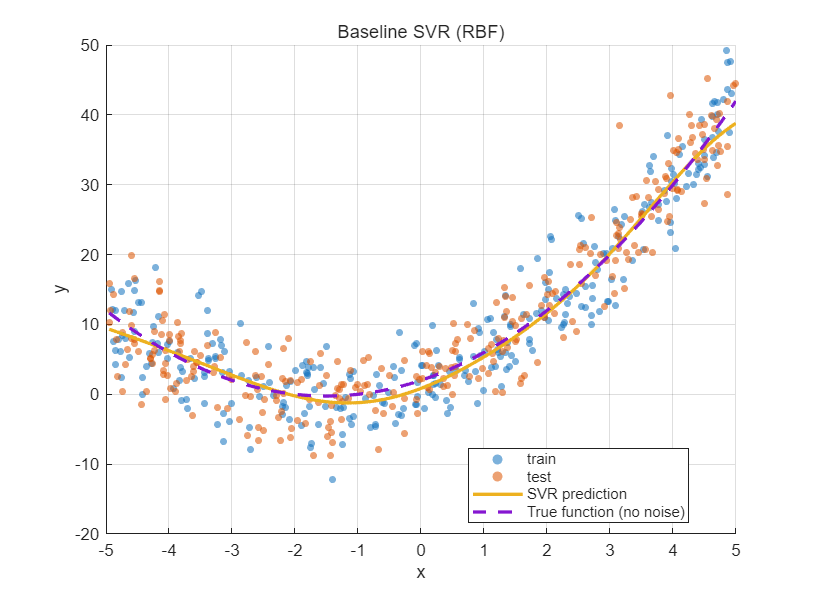


plot_model_curve(mdl_base, muX, sigmaX, trainData, testData, "Baseline SVR (RBF)", true);


=== gamma=0.01 ===


  MAE  = 6.0413
  RMSE = 7.5665
  R2   = 0.6474


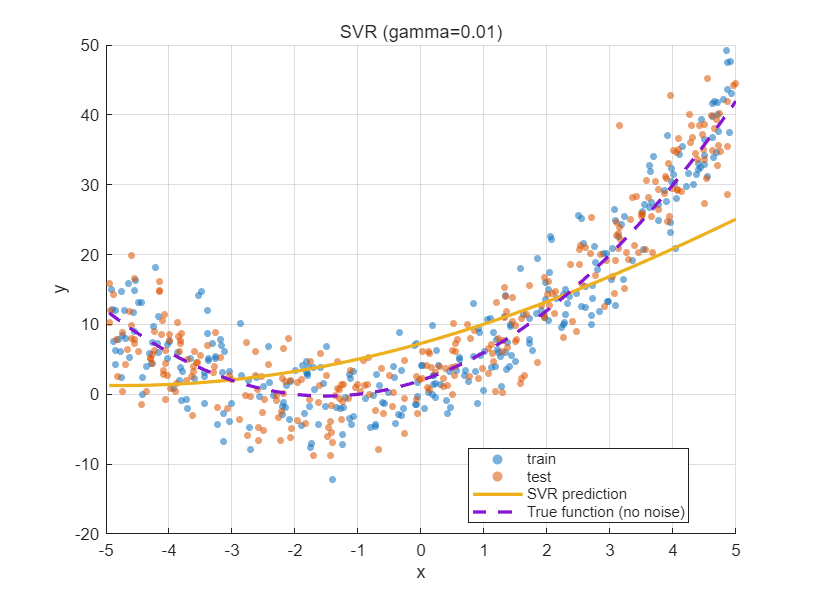


=== gamma=0.05 ===


  MAE  = 3.2833
  RMSE = 4.1914
  R2   = 0.8918


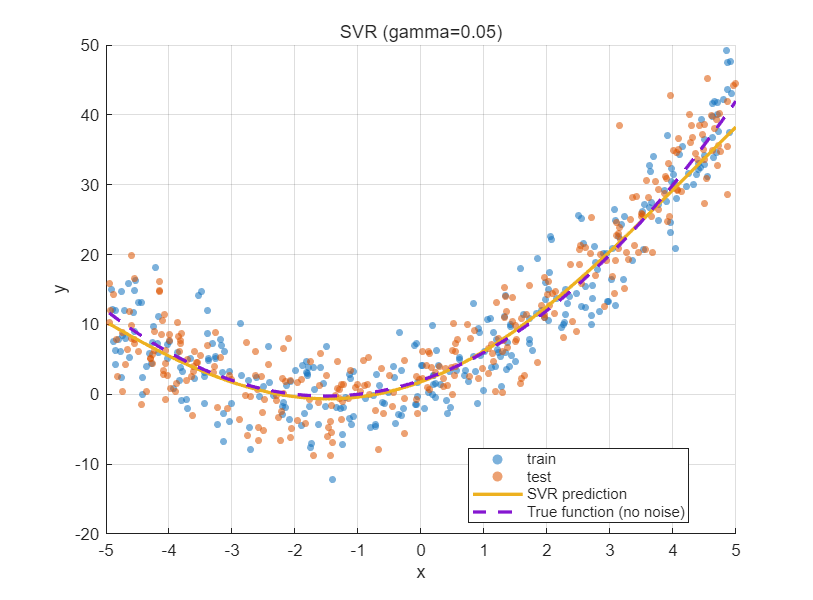


=== gamma=0.1 ===


  MAE  = 3.2869
  RMSE = 4.1762
  R2   = 0.8926


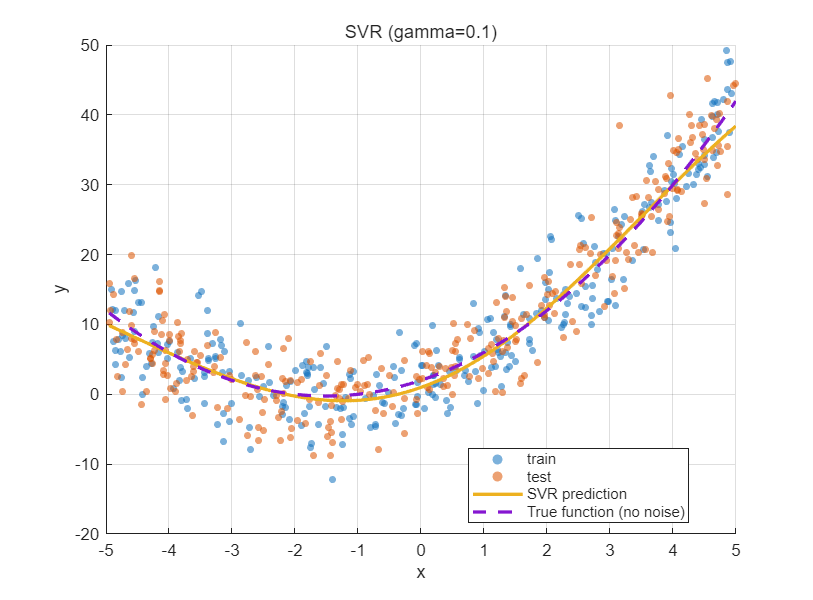


=== gamma=0.5 ===


  MAE  = 3.3049
  RMSE = 4.1737
  R2   = 0.8927


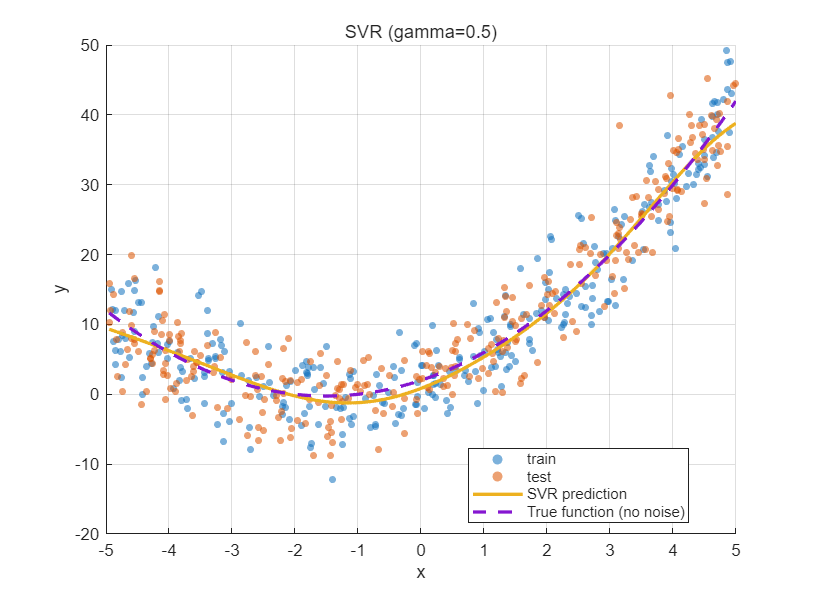


=== gamma=1 ===


  MAE  = 3.2954
  RMSE = 4.1642
  R2   = 0.8932


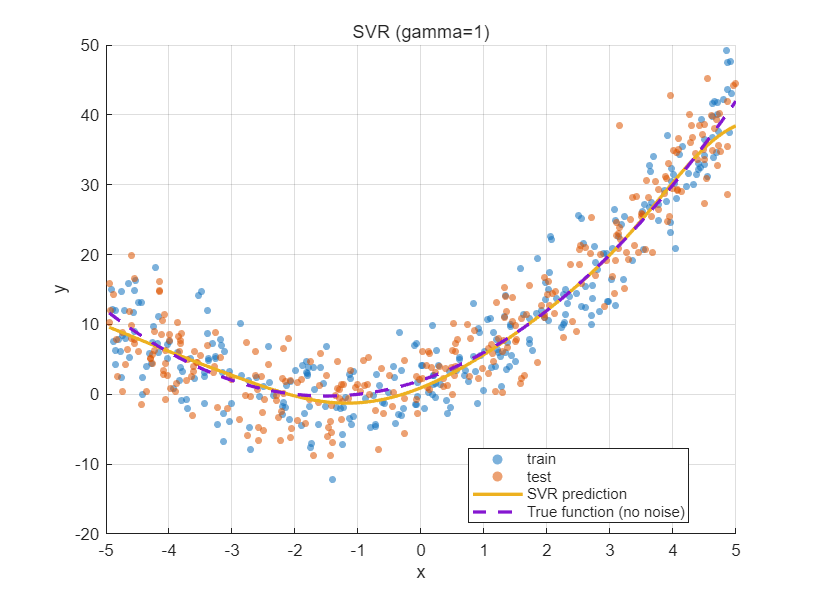


=== gamma=5 ===


  MAE  = 3.4022
  RMSE = 4.3476
  R2   = 0.8836


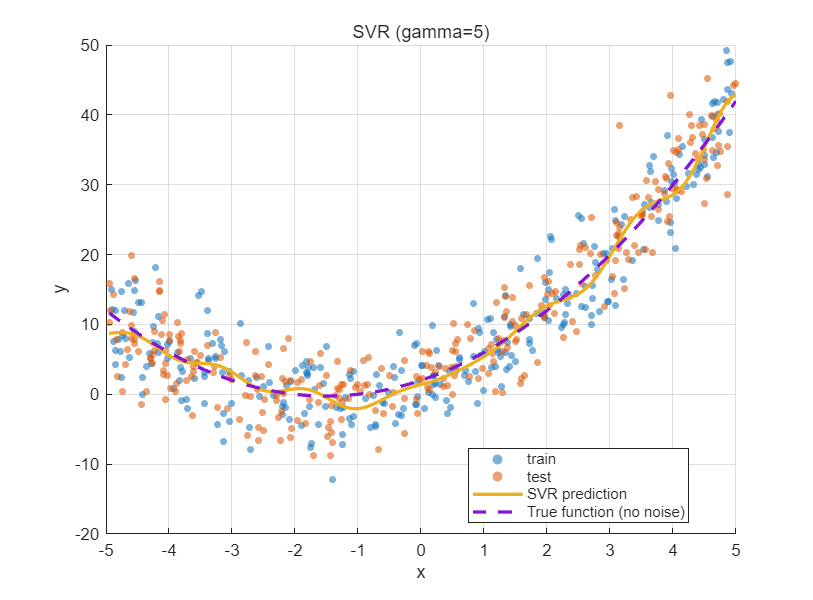


%% 3) 手动观察 gamma 对拟合复杂度的影响（可选批量画图）
SHOW_GAMMA_PLOTS = true;
gammas = [0.01, 0.05, 0.1, 0.5, 1, 5];

for g = gammas
    ks = gamma_to_kernelscale(g);

    mdl = fitrsvm( ...
        Xtr_z, y_train, ...
        "KernelFunction","gaussian", ...
        "BoxConstraint",C0, ...
        "KernelScale",ks, ...
        "Epsilon",epsilon0 ...
    );

    pred = predict(mdl, Xte_z);

    fprintf("\n=== gamma=%g ===\n", g);
    regression_report(y_test, pred, "  ");

    if SHOW_GAMMA_PLOTS
        plot_model_curve(mdl, muX, sigmaX, trainData, testData, sprintf("SVR (gamma=%g)", g), true);
    end
end


%% 4) Bayesian Optimization：搜索 C / gamma / epsilon（5-fold CV，可并行）
k = 5;
rng(42); % 固定 bayesopt 的随机性（可复现）

% 并行池（可选）
USE_PARALLEL = true;
if USE_PARALLEL
    try
        pool = gcp("nocreate");
        if isempty(pool)
            parpool("threads"); % 也可以用 parpool("local")
        end
    catch
        warning("未能启动并行池，将以串行方式运行。");
        USE_PARALLEL = false;
    end
end

正在使用 'threads' 配置文件启动并行池(parpool)...
已连接到具有 8 个工作进程的并行池。


正在将目标函数复制到工作进程...
已将目标函数复制到工作进程。
|==============================================================================================================================|
| Iter | Active  | Eval   | Objective   | Objective   | BestSoFar   | BestSoFar   |         logC |     logGamma |       logEps |
|      | workers | result |             | runtime     | (observed)  | (estim.)    |              |              |              |
|==============================================================================================================================|
|    1 |       3 | Accept |       6.275 |      1.0758 |      4.4012 |      4.4012 |       2.8113 |      -4.3241 |      -2.8276 |
|    2 |       3 | Best   |      4.4012 |      1.1989 |      4.4012 |      4.4012 |       6.3812 |      -5.1398 |       -5.606 |
|    3 |       3 | Accept |      4.5541 |      1.0888 |      4.4012 |      4.4012 |       2.7253 |       2.5679 |      -6.4049 |
|    4 |       3 | Accept |       4.466 |      1.1126 |      4.4

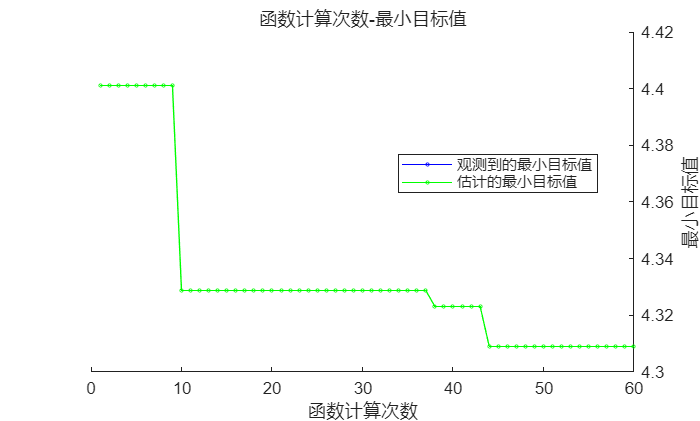


__________________________________________________________
优化完成。
达到 MaxObjectiveEvaluations 60。
函数计算总次数: 60
总历时: 19.6154 秒
总目标函数计算时间: 44.5742

观测到的最佳可行点:
    logC     logGamma    logEps 
    _____    ________    _______

    6.488    -4.5171     0.60487

观测到的目标函数值 = 4.3091
估计的目标函数值 = 4.3091
函数计算时间 = 0.039664

估计的最佳可行点(根据模型):
    logC     logGamma    logEps 
    _____    ________    _______

    6.488    -4.5171     0.60487

估计的目标函数值 = 4.3091
估计的函数计算时间 = 0.09118




% 在 log 空间定义搜索变量（更合理）
vars = [
    optimizableVariable("logC",     [log(1e-2), log(1e3)], "Type","real")
    optimizableVariable("logGamma", [log(1e-3), log(1e2)], "Type","real")
    optimizableVariable("logEps",   [log(1e-3), log(2.0)], "Type","real")
];

% 目标函数：返回 K-fold CV 的 RMSE（越小越好）
objFcn = @(T) svr_cv_objective(T, X_train, y_train, k);

% 运行贝叶斯优化
results = bayesopt( ...
    objFcn, vars, ...
    "IsObjectiveDeterministic", true, ...
    "AcquisitionFunctionName", "expected-improvement-plus", ...
    "MaxObjectiveEvaluations", 60, ...   % 你可改大/改小（越大越精细）
    "NumSeedPoints", 12, ...
    "ExplorationRatio", 0.6, ...
    "Verbose", 1, ...
    "UseParallel", USE_PARALLEL, ...
    "PlotFcn", {@plotMinObjective, @plotObjectiveModel} ...
);


bestTbl = results.XAtMinObjective;
best_rmse = results.MinObjective;

best_params = struct();
best_params.C       = exp(bestTbl.logC);
best_params.gamma   = exp(bestTbl.logGamma);
best_params.epsilon = exp(bestTbl.logEps);

disp(" ");

disp("=== BayesianOpt best result (CV) ===");

=== BayesianOpt best result (CV) ===


fprintf("Best CV RMSE: %.4f\n", best_rmse);

Best CV RMSE: 4.3091


fprintf("Best params: C=%.6g, gamma=%.6g, epsilon=%.6g\n", ...
    best_params.C, best_params.gamma, best_params.epsilon);

Best params: C=657.231, gamma=0.0109203, epsilon=1.83101



%% 5) 用最优参数在全训练集上重训，并在测试集评估
ks_best = gamma_to_kernelscale(best_params.gamma);

mdl_best = fitrsvm( ...
    Xtr_z, y_train, ...
    "KernelFunction","gaussian", ...
    "BoxConstraint",best_params.C, ...
    "KernelScale",ks_best, ...
    "Epsilon",best_params.epsilon ...
);

best_pred = predict(mdl_best, Xte_z);

disp(" ");

disp("=== Best SVR on test set ===");

=== Best SVR on test set ===


best_metrics = regression_report(y_test, best_pred, "");

MAE  = 3.2686
RMSE = 4.1483
R2   = 0.8940


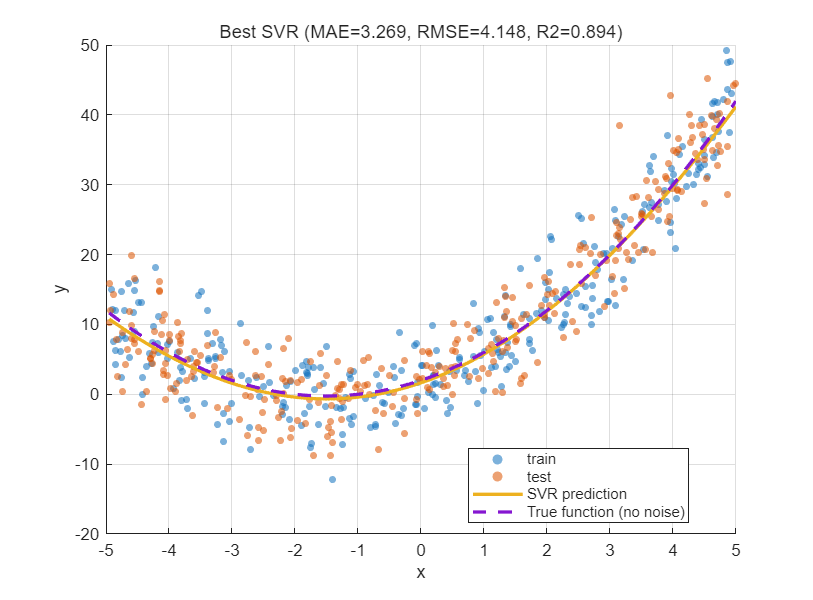


plot_model_curve( ...
    mdl_best, muX, sigmaX, trainData, testData, ...
    sprintf("Best SVR (MAE=%.3f, RMSE=%.3f, R2=%.3f)", best_metrics.mae, best_metrics.rmse, best_metrics.r2), ...
    true ...
);

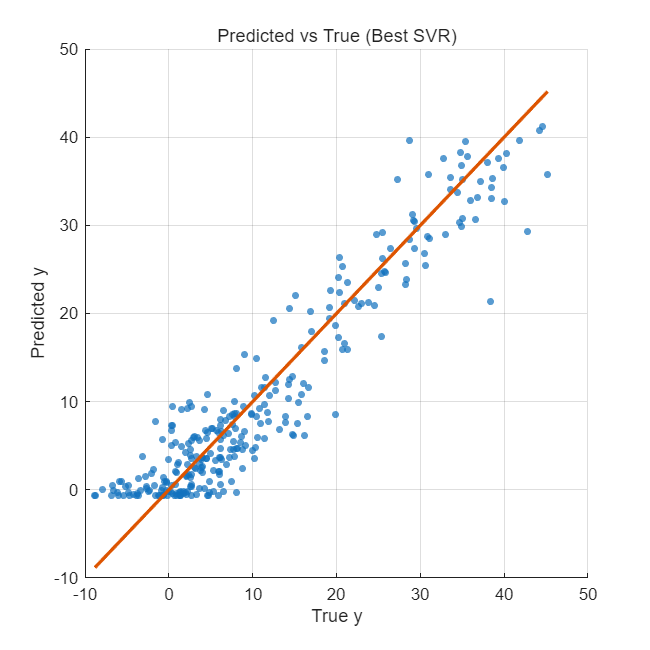


%% 6) 预测 vs 真实：理想情况点落在 y=x 对角线附近
figure("Position",[100 100 520 520]);
scatter(y_test, best_pred, 18, "filled", "MarkerFaceAlpha",0.7);
hold on;
minv = min([y_test; best_pred]);
maxv = max([y_test; best_pred]);
plot([minv maxv], [minv maxv], "LineWidth",2);
title("Predicted vs True (Best SVR)");
xlabel("True y"); ylabel("Predicted y");
grid on;
hold off;

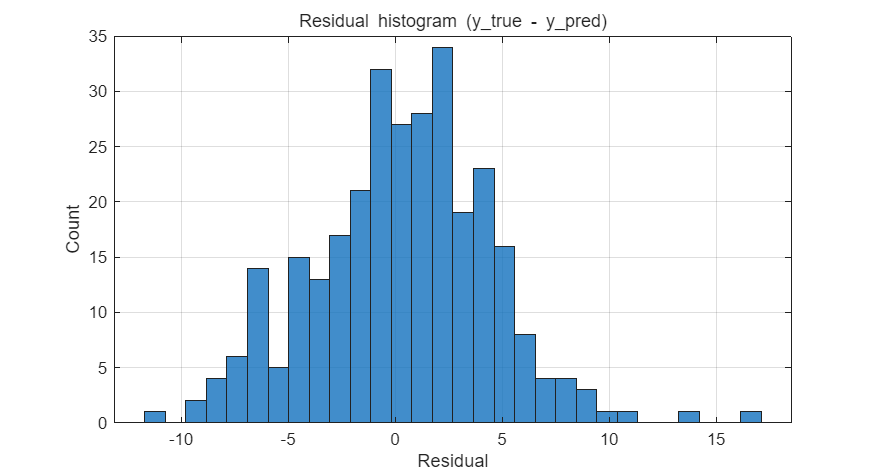


%% 7) 残差分布：residual = y_true - y_pred
residual = y_test - best_pred;
figure("Position",[100 100 700 380]);
histogram(residual, 30, "FaceAlpha",0.8);
title("Residual histogram (y\_true - y\_pred)");
xlabel("Residual"); ylabel("Count");
grid on;


toc;  % 对应 Python 的 toc()

历时 24.099280 秒。



%% ====================== Local functions ======================

function df = make_regression_dataset(n, seed, noise_std)
    rng(seed);
    x = -5 + 10 * rand(n,1);                 % Uniform[-5,5]
    noise = noise_std * randn(n,1);          % N(0, noise_std^2)
    y = 2 + 3*x + x.^2 + noise;
    df = struct("x", x, "y", y);
end

function y = true_function(x)
    y = 2 + 3*x + x.^2;
end

function plot_regression_scatter(train, test, ttl)
    figure("Position",[100 100 650 480]);
    scatter(train.x, train.y, 18, "filled", "MarkerFaceAlpha",0.7); hold on;
    scatter(test.x,  test.y,  18, "filled", "MarkerFaceAlpha",0.7);
    title(ttl);
    xlabel("x"); ylabel("y");
    legend("train","test","Location","best");
    grid on; hold off;
end

function plot_model_curve(mdl, muX, sigmaX, train, test, ttl, show_truth)
    x_min = min([train.x; test.x]);
    x_max = max([train.x; test.x]);
    x_grid = linspace(x_min, x_max, 400).';
    x_grid_z = (x_grid - muX) ./ sigmaX;

    y_hat = predict(mdl, x_grid_z);

    figure("Position",[100 100 650 480]);
    scatter(train.x, train.y, 18, "filled", "MarkerFaceAlpha",0.55); hold on;
    scatter(test.x,  test.y,  18, "filled", "MarkerFaceAlpha",0.55);
    plot(x_grid, y_hat, "LineWidth",2);

    if show_truth
        plot(x_grid, true_function(x_grid), "--", "LineWidth",2);
        legend("train","test","SVR prediction","True function (no noise)","Location","best");
    else
        legend("train","test","SVR prediction","Location","best");
    end

    title(ttl);
    xlabel("x"); ylabel("y");
    grid on; hold off;
end

function metrics = regression_report(y_true, y_pred, prefix)
    mae = mean(abs(y_true - y_pred));
    rmse = sqrt(mean((y_true - y_pred).^2));

    % R2 = 1 - SSE/SST
    sse = sum((y_true - y_pred).^2);
    sst = sum((y_true - mean(y_true)).^2);
    r2 = 1 - sse/sst;

    fprintf("%sMAE  = %.4f\n", prefix, mae);
    fprintf("%sRMSE = %.4f\n", prefix, rmse);
    fprintf("%sR2   = %.4f\n", prefix, r2);

    metrics = struct("mae",mae,"rmse",rmse,"r2",r2);
end

function ks = gamma_to_kernelscale(gamma)
    % sklearn RBF: K(x,x')=exp(-gamma*||x-x'||^2)
    % MATLAB gaussian: exp(-||x-x'||^2/(2*KernelScale^2))
    % => gamma = 1/(2*KernelScale^2) => KernelScale = sqrt(1/(2*gamma))
    ks = sqrt(1 / (2 * gamma));
end

function out = svr_cv_objective(T, X, y, k)
    % bayesopt 传进来的 T 是 table，包含 logC/logGamma/logEps
    C = exp(T.logC);
    gamma = exp(T.logGamma);
    epsv = exp(T.logEps);

    ks = gamma_to_kernelscale(gamma);

    % 固定 CV 划分以保证目标函数"确定性"（否则 bayesopt 会更抖）
    rng(123);
    cvp = cvpartition(numel(y), "KFold", k);

    rmse_folds = zeros(k,1);

    for fold = 1:k
        trIdx = training(cvp, fold);
        vaIdx = test(cvp, fold);

        Xtr = X(trIdx);  ytr = y(trIdx);
        Xva = X(vaIdx);  yva = y(vaIdx);

        % 每折只用训练折拟合 scaler（严格避免泄漏）
        [Xtr_z, mu, sig] = zscore(Xtr);
        Xva_z = (Xva - mu) ./ sig;

        mdl = fitrsvm( ...
            Xtr_z, ytr, ...
            "KernelFunction","gaussian", ...
            "BoxConstraint", C, ...
            "KernelScale", ks, ...
            "Epsilon", epsv ...
        );

        pred = predict(mdl, Xva_z);
        rmse_folds(fold) = sqrt(mean((yva - pred).^2));
    end

    out = mean(rmse_folds); % bayesopt 默认最小化
end
